# Interpolare spline

## Probleme

P1. 

- Pentru fiecare tip de spline scrieti o functie care calculeaza coeficientii spline-ului, daca se dau nodurile si valorile functiei.

% script de testare pentru functiile de calcul al coeficientilor spline
% caz 1: date simple pentru verificare de baza
x1 = [0 1 2 3 4];
y1 = [0 1 0 1 0];

% caz 2: date cu discontinuitate in derivata
x2 = [0 1 2 3 4 5];
y2 = [0 0 1 1 0 0];

% caz 3: date neuniform distribuite
x3 = [0 0.5 0.75 2 4.5 6];
y3 = [1 0.9 0.5 0 0.6 1.2];

% caz 4: functie cu valori negative
x4 = [-3 -2 -1 0 1 2 3];
y4 = [9 4 1 0 1 4 9];

% caz 5: functie trigonometrica esantionata
x5 = linspace(0, 2*pi, 8);
y5 = sin(x5);

% testam toate tipurile de spline pentru fiecare set de date
coef_natural1 = spline_natural(x1, y1);
coef_natural2 = spline_natural(x2, y2);
coef_natural3 = spline_natural(x3, y3);
coef_natural4 = spline_natural(x4, y4);
coef_natural5 = spline_natural(x5, y5);


coef_complet1 = spline_complet(x1, y1, 0, 0);  % derivate la capete = 0
coef_complet2 = spline_complet(x2, y2, 1, -1); % derivate la capete specificate
coef_complet3 = spline_complet(x3, y3, 0.5, 0.2);
coef_complet4 = spline_complet(x4, y4, -6, 6); % derivate care corespund lui y=x^2
coef_complet5 = spline_complet(x5, y5, cos(x5(1)), cos(x5(end))); % derivatele exacte


coef_deriv2_1 = spline_deriv2(x1, y1, 0, 0);  % derivate secunde la capete = 0
coef_deriv2_2 = spline_deriv2(x2, y2, 2, 2);  % derivate secunde nenule
coef_deriv2_3 = spline_deriv2(x3, y3, 1, 1);
coef_deriv2_4 = spline_deriv2(x4, y4, 2, 2);  % derivata a doua exacta pentru y=x^2
coef_deriv2_5 = spline_deriv2(x5, y5, -sin(x5(1)), -sin(x5(end))); % derivatele exacte

coef_deboor1 = spline_deboor(x1, y1);
coef_deboor2 = spline_deboor(x2, y2);
coef_deboor3 = spline_deboor(x3, y3);
coef_deboor4 = spline_deboor(x4, y4);
coef_deboor5 = spline_deboor(x5, y5);

% verificam rezultatele pentru primul set de date
fprintf('\nVerificare set de date 1:\n');


Verificare set de date 1:


verificare(x1, y1, coef_natural1, 'spline_natural');

Erori de interpolare pentru spline_natural: max = 2.220446e-16, medie = 4.440892e-17
Primii coeficienti: [0.000000, 1.714286, 0.000000, -0.714286]


verificare(x1, y1, coef_complet1, 'spline_complet');

Erori de interpolare pentru spline_complet: max = 1.110223e-16, medie = 2.220446e-17
Primii coeficienti: [0.000000, 0.000000, 3.000000, -2.000000]


verificare(x1, y1, coef_deriv2_1, 'spline_deriv2');

Erori de interpolare pentru spline_deriv2: max = 2.220446e-16, medie = 4.440892e-17
Primii coeficienti: [0.000000, 1.714286, 0.000000, -0.714286]


verificare(x1, y1, coef_deboor1, 'spline_deboor');

Erori de interpolare pentru spline_deboor: max = 2.000000e+00, medie = 8.000000e-01
Primii coeficienti: [1.000000, -4.000000, 4.000000, 0.000000]



% comparam cu functia spline din MATLAB
pp = spline(x1, y1);
coef_matlab = zeros(length(x1)-1, 4);
for i = 1:length(x1)-1
    coef_matlab(i,:) = pp.coefs(i,:);
end
verificare(x1, y1, coef_matlab, 'spline MATLAB');

Erori de interpolare pentru spline MATLAB: max = 2.000000e+00, medie = 8.000000e-01
Primii coeficienti: [1.000000, -4.000000, 4.000000, 0.000000]


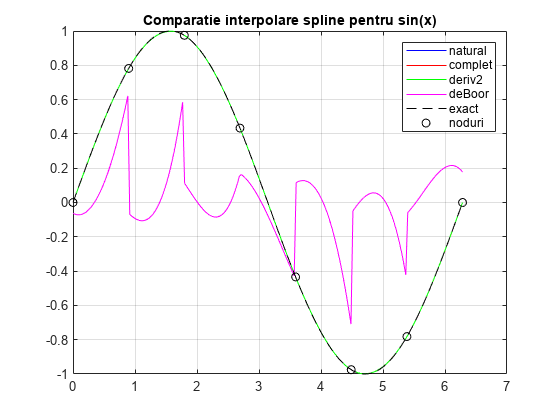


% reprezentam grafic pentru ultimul set de date (functia sinus)
xx = linspace(min(x5), max(x5), 200);
y_natural = eval_spline(x5, coef_natural5, xx);
y_complet = eval_spline(x5, coef_complet5, xx);
y_deriv2 = eval_spline(x5, coef_deriv2_5, xx);
y_deboor = eval_spline(x5, coef_deboor5, xx);
y_exact = sin(xx);

figure;
plot(xx, y_natural, 'b-', xx, y_complet, 'r-', xx, y_deriv2, 'g-', ...
     xx, y_deboor, 'm-', xx, y_exact, 'k--', x5, y5, 'ko');
legend('natural', 'complet', 'deriv2', 'deBoor', 'exact', 'noduri');
title('Comparatie interpolare spline pentru sin(x)');
grid on;


% calculam si afisam erorile fata de functia exacta
err_natural = max(abs(y_natural - y_exact));
err_complet = max(abs(y_complet - y_exact));
err_deriv2 = max(abs(y_deriv2 - y_exact));
err_deboor = max(abs(y_deboor - y_exact));

fprintf('\nErori maxime fata de sin(x):\n');


Erori maxime fata de sin(x):


fprintf('spline_natural: %e\n', err_natural);

spline_natural: 2.001817e-03


fprintf('spline_complet: %e\n', err_complet);

spline_complet: 2.155972e-03


fprintf('spline_deriv2: %e\n', err_deriv2);

spline_deriv2: 2.001817e-03


fprintf('spline_deboor: %e\n', err_deboor);

spline_deboor: 1.049558e+00


2. Evaluati spline-ul pe o multime de puncte, daca se dau nodurile, punctele si coeficientii.

Test 1 - Functie liniara:
Puncte de evaluare:     0.5000    1.5000    2.5000         0    3.0000

Valori calculate:     1.5000    2.5000    3.5000    1.0000    4.0000

Valori asteptate:     1.5000    2.5000    3.5000    1.0000    4.0000

Eroare maxima: 0.000000e+00

Test 2 - Functie sin(x):
Puncte de evaluare:     2.2037    2.3789    3.3478    3.4567    3.6885    3.9111    4.0484    5.0993    5.5037    5.8999

Valori calculate:     0.8048    0.6894   -0.2050   -0.3102   -0.5196   -0.6943   -0.7859   -0.9245   -0.7029   -0.3730

Valori asteptate:     0.8063    0.6909   -0.2048   -0.3100   -0.5201   -0.6958   -0.7875   -0.9261   -0.7029   -0.3740

Eroare maxima: 1.600756e-03

Test 3 - Evaluare in noduri:
Puncte de evaluare:      0     1     2     3     4     5

Valori calculate:          0    1.0000         0    1.0000         0    1.0000

Valori asteptate:      0     1     0     1     0     1

Eroare maxima: 2.220446e-16

Test 4 - Puncte in afara intervalului:
Puncte de evaluare:       

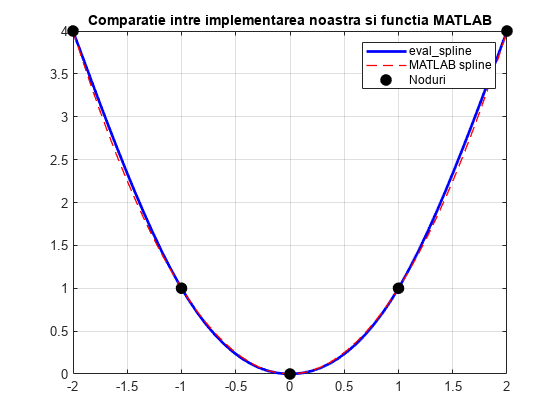

Test 6 - Performanta:
Timp de evaluare pentru 10000 puncte: 0.006032 secunde
Media timp per punct: 6.031800e-07 secunde


test_eval_spline();

P2. Desenati o curba spline cubica parametrica ce trece printr-o multime de puncte date.

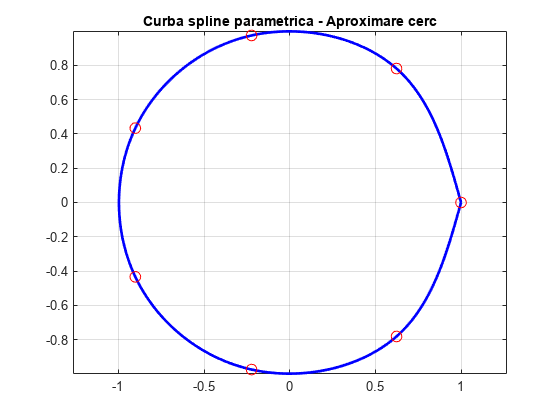

% exemplu de utilizare a curbei parametrice spline
% definim curbă circulară
t = linspace(0, 2*pi, 8);
x_circ = cos(t);
y_circ = sin(t);

% calculam spline-urile pentru ambele coordonate
coef_x = spline_natural(t, x_circ);
coef_y = spline_natural(t, y_circ);

% evaluam curba pe puncte dense
tt = linspace(0, 2*pi, 200);
xx = eval_spline(t, coef_x, tt);
yy = eval_spline(t, coef_y, tt);

% reprezentam grafic
figure;
plot(xx, yy, 'b-', 'LineWidth', 2);
hold on;
plot(x_circ, y_circ, 'ro', 'MarkerSize', 8);
title('Curba spline parametrica - Aproximare cerc');
axis equal;
grid on;


% afisam eroarea fata de cercul exact
exact_x = cos(tt);
exact_y = sin(tt);
eroare = sqrt((xx-exact_x).^2 + (yy-exact_y).^2);
disp(['Eroarea maxima fata de cerc: ', num2str(max(eroare))]);

Eroarea maxima fata de cerc: 0.043911


P3. Literele PostScript si TrueType se genereaza cu spline parametrice, utilizand doar cateva puncte pentru fiecare litera.

(a) Creati si imprimati litera de mana definita de urmatoarele date:

`t``  =  ``0`   `1`   `2`   `3`   `4`   `5`   `6`   `7`   `8`   `9`   `10`   `11`  

`x``  =  ``3` `1.75` `0.90` `0` `0.50` `1.50` `3.25` `4.25` `4.25` `3` `3.75` `6.00`  

`y``  =  ``4` `1.60` `0.50` `0` `1.00` `0.50` `0.50` `2.25` `4.00` `4` `4.25` `4.25`  

(b) In acelasi sistem de axe, desenati litera impreuna cu litera de dimensiune dubla. (Comanda `2*x` va dubla dimensiunea fontului in directia x

(c) Animati desenarea literei utilizand comanda `comet`.

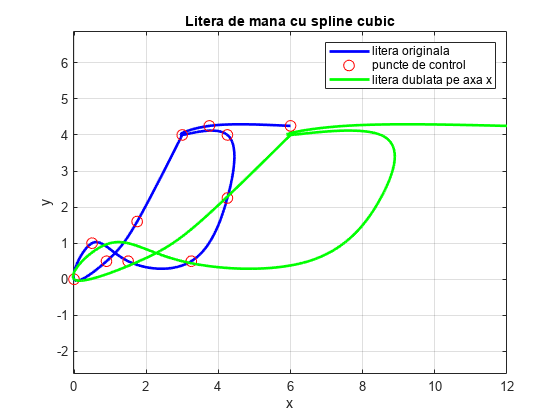

% date pentru litera
t = [0 1 2 3 4 5 6 7 8 9 10 11];
x = [3 1.75 0.90 0 0.50 1.50 3.25 4.25 4.25 3 3.75 6.00];
y = [4 1.60 0.50 0 1.00 0.50 0.50 2.25 4.00 4 4.25 4.25];

% calculam coeficientii pentru coordonatele x si y
coef_x = spline_natural(t, x);
coef_y = spline_natural(t, y);

% evaluam spline-ul pe o multime densa de puncte
tt = linspace(0, 11, 500);
xx = eval_spline(t, coef_x, tt);
yy = eval_spline(t, coef_y, tt);

% desenam litera
figure;
plot(xx, yy, 'b-', 'LineWidth', 2);
hold on;
plot(x, y, 'ro', 'MarkerSize', 8);
title('Litera de mana cu spline cubic');
xlabel('x');
ylabel('y');
axis equal;
grid on;

% litera cu dimensiune dubla pe axa x
xx2 = 2 * xx;
plot(xx2, yy, 'g-', 'LineWidth', 2);
legend('litera originala', 'puncte de control', 'litera dublata pe axa x');

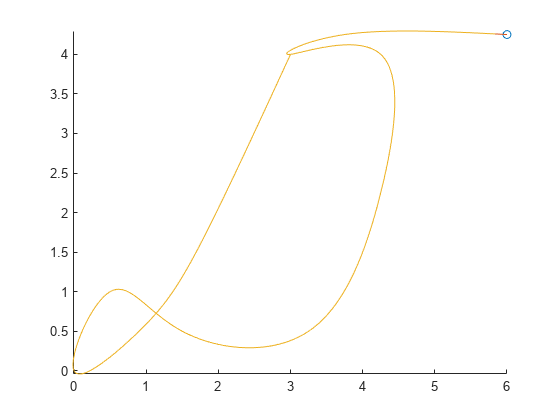


% animarea desenarii literei
figure;
comet(xx, yy);

title('animatie pentru desenarea literei');

(d) Creati si desenati o alta litera.

% date pentru litera 'B' 
t = [0 1 2 3 4 5 6 7 8];
x = [0 0 0 1 2 0 2 1 0];
y = [0 2 4 4 3 2 1 0 0];

% calculam coeficientii pentru coordonatele x si y
coef_x = spline_natural(t, x);
coef_y = spline_natural(t, y);

% evaluam spline-ul pe o multime densa de puncte
tt = linspace(0, 8, 300);
xx = eval_spline(t, coef_x, tt);
yy = eval_spline(t, coef_y, tt);

% desenam litera
figure;
plot(xx, yy, 'b-', 'LineWidth', 2);
hold on;
plot(x, y, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
title('Litera B cu spline cubic');
xlabel('x');
ylabel('y');
axis equal;
grid on;